## Evaluating heat flows at sensor positions

Load data and define query points

close all;
clear all;
clc;
load("solidkiln_longwideoptimized.mat")

Evaluate heat flow at all positions

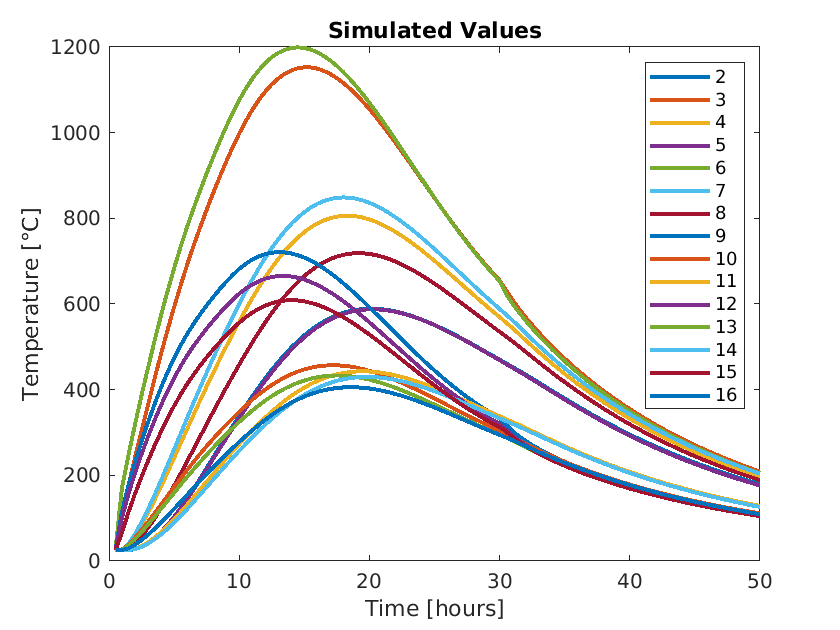

v = linspace(-0.5,0.5,11);
times = [1:100];
zfactor = 10;%1/1.21;
yfactor = 10;%/1.25;
xfactor = 10;%/1.33;

p2 = interpolateTemperature(result,168*xfactor, 164*zfactor, 125*yfactor, times);
p3 = interpolateTemperature(result,121*xfactor, 70*zfactor, 125*yfactor, times);
p4 = interpolateTemperature(result,90*xfactor, 112*zfactor,125*yfactor,  times);
p5 = interpolateTemperature(result,90*xfactor, 159*zfactor,125*yfactor,  times);
p6 = interpolateTemperature(result,53*xfactor, 60*zfactor,125*yfactor,  times);
p7 = interpolateTemperature(result,168*xfactor, 112*zfactor,125*yfactor,  times);
p8 = interpolateTemperature(result,35*xfactor, 126*zfactor,126*yfactor,  times);
p9 = interpolateTemperature(result,200*xfactor, 70*zfactor, 12*yfactor, times);
p10 = interpolateTemperature(result,163*xfactor, 112*zfactor,12*yfactor,  times);
p11 = interpolateTemperature(result,163*xfactor, 158*zfactor,12*yfactor,  times);
p12 = interpolateTemperature(result,121*xfactor, 70*zfactor,12*yfactor,  times);
p13 = interpolateTemperature(result,85*xfactor, 112*zfactor,12*yfactor,  times);
p14 = interpolateTemperature(result,85*xfactor, 162*zfactor,12*yfactor,  times);
p15 = interpolateTemperature(result,90*xfactor, 70*zfactor,12*yfactor,  times);
p16 = interpolateTemperature(result,40*xfactor, 126*zfactor,12*yfactor,  times);

times=times/100*50;

plot(times,p2, 'LineWidth',2)
title('Simulated Values')

hold on
plot(times,p3, 'LineWidth',2)
plot(times,p4, 'LineWidth',2)
plot(times,p5, 'LineWidth',2)
plot(times,p6, 'LineWidth',2)
plot(times,p7, 'LineWidth',2)
plot(times,p8, 'LineWidth',2)
plot(times,p9, 'LineWidth',2)
plot(times,p10, 'LineWidth',2)
plot(times,p11, 'LineWidth',2)
plot(times,p12, 'LineWidth',2)
plot(times,p13, 'LineWidth',2)
plot(times,p14, 'LineWidth',2)
plot(times,p15, 'LineWidth',2)
plot(times,p16, 'LineWidth',2)
xlabel("Time [hours]")
ylabel("Temperature [°C]")
legend('2','3', '4', '5', '6', '7', '8','9', '10', '11', '12', '13', '14', '15', '16')

Evaluate quality of firing over entire oven.

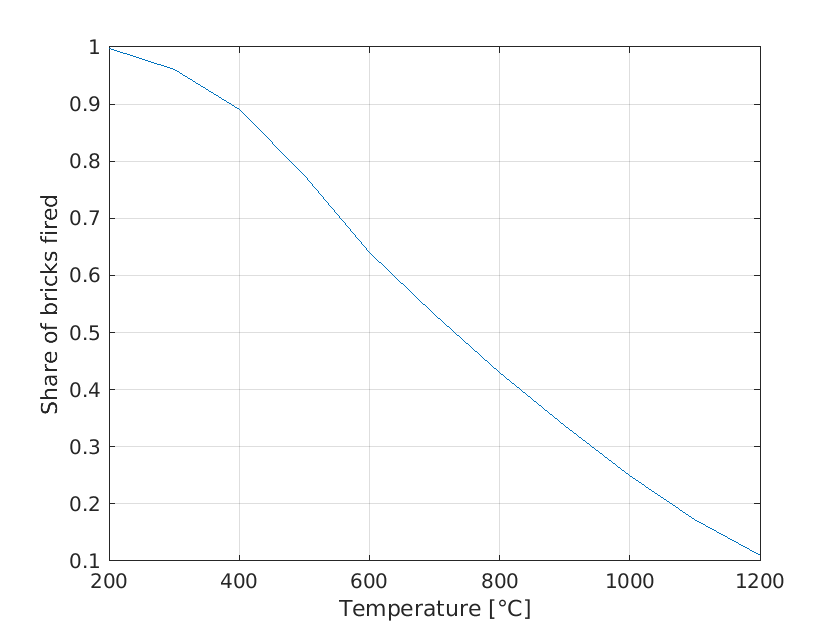


bins = [200, 300, 400, 500, 600, 700, 800, 900, 1000, 1100,1200];
hist=[];
for i = bins
    lowT =find(T<i);
    soaking = T;
    soaking(lowT)=0;
    soaking=soaking~=0;
    soaking_period=sum(soaking, 2);
    sufficient_bricks=soaking_period~=0;
    sufficient_percent=sum(sufficient_bricks)/length(T);
    hist = [hist, sufficient_percent];
    
end
figure
plot(bins, hist)
xlabel('Temperature [°C]')
ylabel('Share of bricks fired')

grid on